# 1. Solving the 1D Heat Equation PDE using explicit FTCS  finite difference discretization

This excersise is focused to numerically solve the heat equation in 1D (also known as diffusion equation) by using finite differences schemes. In one-dimensional medium the heat equation is defined by the following PDE where $\kappa$ is called thermal difussivity, and its units are $\left\lbrack \kappa \right\rbrack =\frac{L^2 }{T}$


$$\frac{\partial u}{\partial t}=\kappa \frac{\partial^2 u}{{\partial x}^2 }$$


**1.1 Finite difference FTCS scheme**

Applying a Forward Time - Central Space (FTCS) finite differences scheme we get:


$$\frac{u_i^{n+1} -u_i^n }{\Delta t}=\kappa \left\lbrack \frac{u_{i+1}^n -2u_i^n +u_{i-1}^n }{{\left(\Delta x\right)}^2 }\right\rbrack +O\left(\Delta t,{\Delta x}^2 \right)\;\;\mathrm{where}\;O\left(\Delta t,{\Delta x}^2 \right)\;\;\mathrm{is}\;\mathrm{the}\;\mathrm{truncation}\;\mathrm{error}\;\;$$


Let $r=\kappa \frac{\Delta t}{{\left(\Delta x\right)}^2 }$, solving for $u_i^{n+1}$

$u_i^{n+1}$=${\mathrm{ru}}_{i-1}^n +\left(1-2r\right)u_i^n +ru_{i+1}^n$ 

for i=2 to N-1, Let $A=\left\lbrack \begin{array}{ccccc}
\left(1-2r\right) & r & 0 & \cdots  & 0\\
r & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & \ddots  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & r\\
0 & \cdots  & 0 & r & \left(1-2r\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccc}
1 & 0 & 0 & \cdots  & 0\\
0 & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & \ddots  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & 0\\
0 & \cdots  & 0 & 0 & 1
\end{array}\right\rbrack +r\left\lbrack \begin{array}{ccccc}
-2 & 1 & 0 & \cdots  & 0\\
1 & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & \ddots  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & 1\\
0 & \cdots  & 0 & 1 & -2
\end{array}\right\rbrack =I+\textrm{rT}$

Thus, $U^{n+1} =AU^n$

Initial Conditions:


$$u\left(x,0\right)=f\left(x\right)\;\;\;\;\;\mathrm{where}\;f\left(x\right)=\mathrm{sin}\left(\frac{\pi x}{L}\right)$$


Boundary conditions:


$$u\left(0,t\right)=0\;\;u\left(L,t\right)=0\;\;\mathrm{for}\;\mathrm{all}\;t>0$$


**1.2 Von Neumman Stability Analisis**

${\mathrm{Inserting}\;\mathrm{the}\;\mathrm{error}\;\mathrm{function}\;E_{\mathrm{pq}} =e^{i\beta p\Delta x} Z^q \;\;\;\;\;\mathrm{into}\;\mathrm{the}\;\mathrm{equation}\;\;\;\;\;u}_i^{n+1}$=${\mathrm{ru}}_{i-1}^n +\left(1-2r\right)u_i^n +ru_{i+1}^n$

$e^{i\beta p\Delta x} Z^{q+1}$=$re^{i\beta \left(p-1\right)\Delta x} Z^q +\left(1-2r\right)e^{i\beta p\Delta x} Z^q +re^{i\beta \left(p+1\right)\Delta x} Z^q$


$$Z=1-2r+r\left(e^{i\beta \Delta x} +e^{-i\beta \Delta x} \right)=1-2r+2\mathrm{rcos}\left(\beta \Delta x\right)=1-2r+2r\left(1-2\mathrm{sin}\left(\frac{\beta \Delta x}{2}\right)\right)=1-4\mathrm{rsin}\left(\frac{\beta \Delta x}{2}\right)$$


For stability $|Z|=1$


$$-1\le 1-4\mathrm{rsin}\left(\frac{\beta \Delta x}{2}\right)\le 1\;\;\;\;\;$$



$$r\le \frac{1}{2}$$


**1.3 Analytical Solution**

The exact solution is given by the following equation:


$$u\left(x,t\right)=\mathrm{sin}\left(\frac{\pi x}{L}\right)\mathrm{exp}\left(-\frac{\kappa \pi^2 x}{L^2 }\right)$$


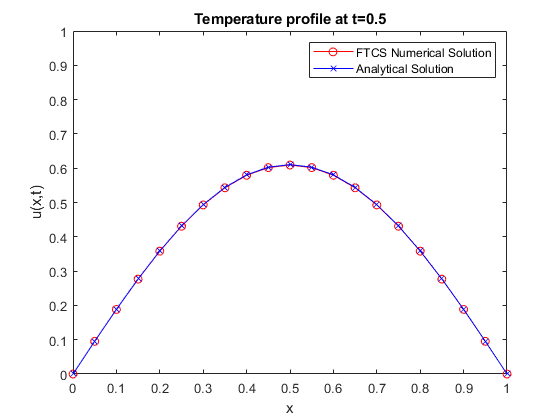

clear variables
close all
% Constants
k=0.1; %Thermal Difussivity
%% Space discretization
L=1; dx=0.05; x=0:dx:L; M=L/dx+1;
%% Time discretization
Tf=0.5; dt=0.0125; t=0:dt:Tf;  N=Tf/dt+1;  % dx^2/(2*k);
r=k*dt/(dx)^2;
%% Initial conditions
U=zeros(M,N); UA=zeros(M,N);
U(2:end-1,1)=sin((pi/L)*x(2:end-1).');
UA(2:end-1,1)=U(2:end-1,1);
%Boundary conditions
U(1,:)=0; U(L,:)=0; UA(1,:)=0; UA(L,:)=0;
%
T=(diag(-2*ones(1,M-2)) + diag(1*ones(1,M-3),1) + diag(1*ones(1,M-3),-1));
A=eye(M-2)+r*T;
for n=2:N
    U(2:end-1,n)=A*U(2:end-1,n-1);
    UA(2:end-1,n)=sin((pi/L)*x(2:end-1).')*exp(-k*pi^2*t(n)/L^2); %Analytical solution
end
plot(x,U(:,N),'r-o')
hold on
plot(x,UA(:,N),'b-x')
xlabel('x'); ylabel('u(x,t)'); title('Temperature profile at t=0.5'); legend('FTCS Numerical Solution','Analytical Solution'); ylim([0.00 1]);

Using the norm 2 of the error :

Error=abs(U(:,:)-UA(:,:));
Nom2_Error=norm(Error(:,N))

Nom2_Error = 0.0039